# Logistic Regression in MATLAB

#### Setup Data

data = load("ex2data1.txt")

data =            34.623659624517          78.0246928153624                         0
          30.2867107682261           43.894997524001                         0
          35.8474087699387          72.9021980270836                         0
          60.1825993862098          86.3085520954683                         1
          79.0327360507101          75.3443764369103                         1
          45.0832774766834          56.3163717815305                         0
          61.1066645368477          96.5114258848962                         1
          75.0247455673889          46.5540135411654                         1
          76.0987867022626           87.420569719268                         1
          84.4328199612004          43.5333933107211                         1


Setup Input Features

X = data(:, 1:end-1)

X =            34.623659624517          78.0246928153624
          30.2867107682261           43.894997524001
          35.8474087699387          72.9021980270836
          60.1825993862098          86.3085520954683
          79.0327360507101          75.3443764369103
          45.0832774766834          56.3163717815305
          61.1066645368477          96.5114258848962
          75.0247455673889          46.5540135411654
          76.0987867022626           87.420569719268
          84.4328199612004          43.5333933107211


X = [ones(size(X, 1), 1), X]

X =                          1           34.623659624517          78.0246928153624
                         1          30.2867107682261           43.894997524001
                         1          35.8474087699387          72.9021980270836
                         1          60.1825993862098          86.3085520954683
                         1          79.0327360507101          75.3443764369103
                         1          45.0832774766834          56.3163717815305
                         1          61.1066645368477          96.5114258848962
                         1          75.0247455673889          46.5540135411654
                         1          76.0987867022626           87.420569719268
                         1          84.4328199612004          43.5333933107211


Setup Output Labels

y = data(:, end)

y =      0
     0
     0
     1
     1
     0
     1
     1
     1
     1


Setup initial theta

theta = zeros(1, size(X,2))

theta =      0     0     0



[X_norm, mu, sigma] = scale_features(X)

X_norm =                          1         -1.59421626465764         0.635141394175443
                         1         -1.81710141803407         -1.20148852391424
                         1          -1.5313251573355         0.359483287559047
                         1        -0.280687238217609          1.08092280714159
                         1         0.688061931037553         0.490904851522895
                         1         -1.05667394942895        -0.533053971820772
                         1         -0.23319753758833          1.62997263287794
                         1         0.482082657772537         -1.05839822298677
                         1         0.537279947621063           1.1407640925641
                         1         0.965583887260159         -1.22094762282935


mu =           65.6442740573232          66.2219980881169


sigma =           19.4582222754251          18.5827830393073


#### Perform Gradient Descent

alpha = .001

alpha =                      0.001


num_iters = 100000

num_iters =       100000


[theta, J_History] = gradient_descent(X_norm, y, theta, alpha, num_iters)

theta =           1.26771110772949          3.05538162426961          2.81879933936237


J_History =          0.692996535774427         0.692845963962308         0.692695465088222         0.692545039116809         0.692394686012711         0.692244405740578         0.692094198265062         0.691944063550825         0.691794001562529         0.691644012264846         0.691494095622449          0.69134425160002         0.691194480162245         0.691044781273814         0.690895154899424         0.690745601003777         0.690596119551582         0.690446710507549         0.690297373836399         0.690148109502854         0.689998917471645         0.689849797707507          0.68970075017518          0.68955177483941         0.689402871664949         0.689254040616556         0.689105281658992         0.688956594757028         0.688807979875437            0.688659436979         0.688510966032504          0.68836256700074         0.688214239848505         0.688065984540605         0.687917801041847         0.687769689317048         0.687621649331028         0.687473681048615

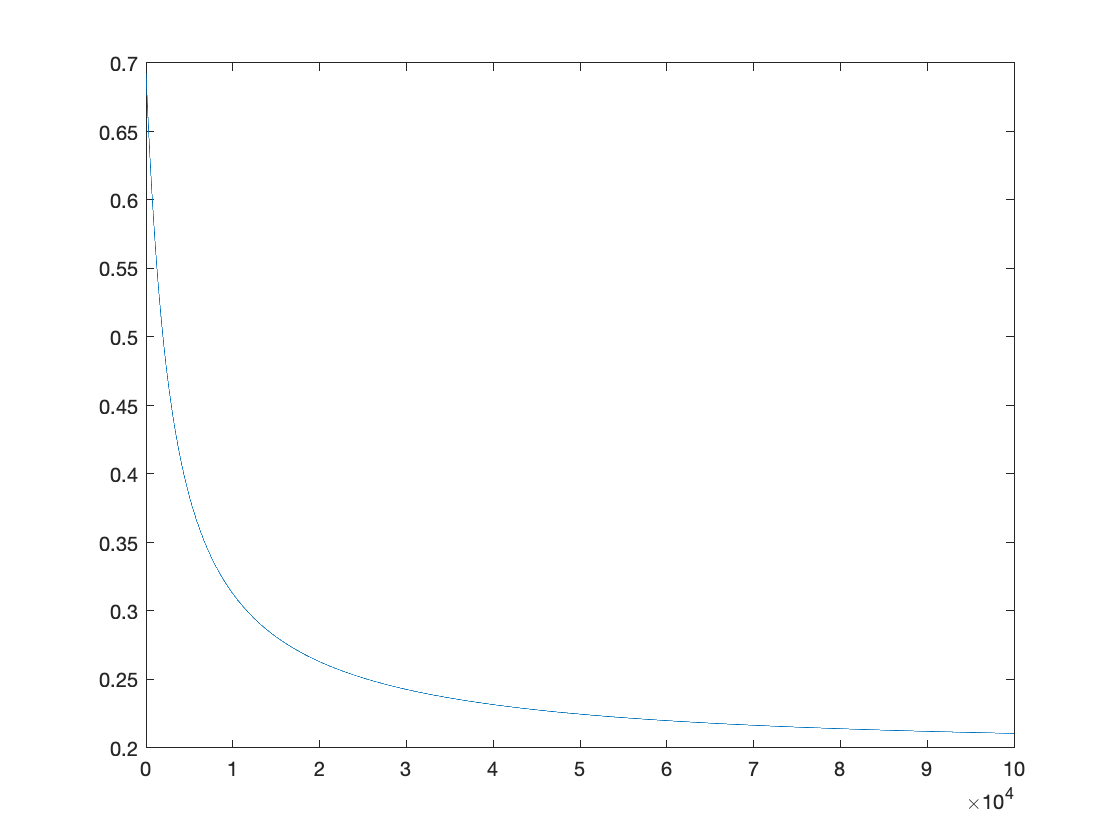

plot(J_History)

theta

theta =           1.26771110772949          3.05538162426961          2.81879933936237
